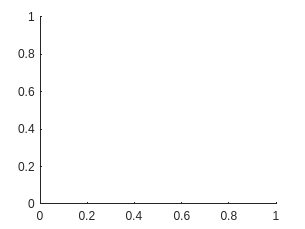

curve=animatedline('LineWidth',1,'Color','k');
curve2=animatedline('LineWidth',1,'Color','k');

R=3

R = 3

r=1;
a=1;
L=R+2*a+0.1;
p=0;
iiu =[0 0];
OR=[R 0];
o=[R-r 0];
or=[R 0];
raddi=0.1*rand(5,1);
X = rand(5,1);
Y = rand(5,1);
centers = [X Y];
t=[1,2,3,4,5,6]

t =      1     2     3     4     5     6


z=[2,4,6,8,10.12]

z =     2.0000    4.0000    6.0000    8.0000   10.1200



%C1=viscircles(O,R);
C1=viscircles([t(:),z(:)],0.5);

Error using horzcat
Dimensions of arrays being concatenated are not consistent.

hold on
for f=1:(360*R)+1
    p=p+1;
    rx1(j)=(R+r)*cosd((r/R)*(j-1));
    ry1(j)=(R+r)*sind((r/R)*(j-1));
    rx2(j)=(R-r)*cosd((r/R)*(j-1));
    ry2(j)=(R-r)*sind((r/R)*(j-1));
    o(j,:)=[rx1(j) ry1(j)];
    o2(j,:)=[rx2(j) ry2(j)];
    x1(j)=a*cosd((1+r/R)*(j-1)+o(j,1));
    y1(j)=a*sind((1+r/R)*(j-1)+o(j,2));
    x2(j)=a*cosd((1-r/R)*(j-1)+o2(j,1));
    y2(j)=-a*sind((1-r/R)*(j-1)+o2(j,2));
    Ra(j)=line([o(j,1) x1(j)],[o(j,2) y2(j)],'color','b');
    Ra2(j)=line([o2(j,1) x2(j)],[o2(j,2) y2(j)],'color','b');
    C2=viscircles(o(j,:),r,'color','b');
    C3=viscircle(o2(j,:),r,'color','b');
    addpoints(curve,x1(j),y1(j));
    addpoints(curve2,x2(j),y2(j));
    drawnow
    grid on
    axis([-L L -L L]);
    F(p)=getframe(gof);
    delete(Ra);
    delete(C2);
    delete(Ra2);
    delete(C3);
end


clc;clear all;
curve=animatedline(LineWidth=1,Color='k')
grid on
%variables
p=0;
for i=1:n
    addpoints(curve,x,y);
    drawnow
    F(p)=getframe(gof)
end
video=VideoWriter('nombre.avi','Motion JPEG AVI')
video.FrameRate=60;
open(video)
writeVideo(video,F);
close(video);